# **Matlab Vision Based Pick and Place**

## **1. Startup (environment)**

%clear workspace
clc
clear
close all force
% there is no function to clear the output window for the live script
% right-click and select "Clear all output"

%check working directory
if ~isfile("main.mlx"); warning('C:\Users\Yash\Desktop\Vision_PnP\Images'); return; end

% Adding file paths
addpath("Images\")
addpath("Matlab_files\")
addpath("Robodk_files\")

%generating a readable backup of the main.mlx file!
FHWS_BACKUP_MLX("main.mlx")

## **2. Startup (main settings)**

% Setting rdk_status as a global variable to use it with all *.m scripts (speed reasons)
global rdk_status

% Flag: image processing with or without RoboDK
rdk_status = false;

manual_img_name = "Snap_real_dark.png"; % only used if RoboDK_off

% default Simulation image files
%-------------------------------
% Snap_sim.jpg
% 
% Snap_sim_w2Red2close.jpg

% default Real image files
%-------------------------
% 
% Snap_real_bright.png
% Snap_real_bright_2.png
% Snap_real_dark.png
% Snap_real_dark_2.png
% Snap_real_wB.png
% Snap_real_wB_bright.png
% Snap_real_wB_dark.png

% Flag: robot motion in simulation or on the real robot
% only used if rdk_status=RoboDK_on
rdk_real_robot = false ;

% Starting RoboDK and loading simulation cell
if rdk_status == true
    global RDK; % setting RoboDK as global to use it with all *.m scripts (speed reasons)
    RDK = Robolink(); % starting RoboDK library
    
    path_rdk = strcat( pwd , '\Robodk_files\'); % setting RoboDK path
    copyfile Robodk_files\ur5e_station.rdk Robodk_files\ur5e_station_temp.rdk % copy of station to protect against unintended changes
    RDK.AddFile([path_rdk, 'ur5e_station_temp.rdk']); % open RoboDK and station
    
    % Set the RoboDK to simulation or real_robot motion
    RDK.setParam('RUN_MODE', num2str(rdk_real_robot))
    
    % Set image folder for camera
    RDK.setParam('PATH_MATLAB', pwd)
    RDK.setParam('PATH_MATLAB_IMAGES', strcat( pwd , '\Images\'))
    
    % Set simulation or real_robot motion
    if rdk_real_robot == false
        RDK.setRunMode(RDK.RUNMODE_SIMULATE)
    else
        RDK.setRunMode(RDK.RUNMODE_RUN_ROBOT) % !! not working yet !! (You can not call py-Programm in real mode :( )
    end
    
    %robot = RDK.Item('UR5e'); % select UR5e node in RoboDK
    %robot.Disconnect();
    robot = RDK.Item('UR5e'); % select UR5e node in RoboDK
    robot.Connect();
    RDK.setSimulationSpeed(0.5); % set simulation speed
end


## **3. Image generation**

Taking a picture from RoboDK: either in the simulated or the real environment (for details, see the Python code in RoboDK).

Then display the raw image in Matlab.

% Move the robot to default picture position and take a picture
if rdk_status == true
    RDK_Ur5e_HOME() % move robot to default picture position
    RDK_4KA_SNAP() % take picture
    % set simulation or real_robot as picture input
    if rdk_real_robot == true
        im = iread('Snap_real.png','single');
    else
        im = iread('Snap_sim.jpg','single');
    end
else
    % No RoboDK, we work on a stored image
    im = iread(manual_img_name,'single');
end

disp("Camera image (raw)")

Camera image (raw)


image_raw = imtool(im);
image_raw.Name = "camera image (raw)";
close(image_raw) % closes external image window - comment out if you want to keep it open

## **4. Image processing**

Optimize the previously loaded raw image for better detection of the RGB colours.

% Split image in R/G/B values and display output
[R,G,B] = imsplit(im);
disp("Split image in R/G/B")

Split image in R/G/B


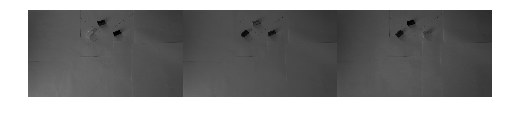

montage({R,G,B},'Size',[1 3])


disp("Adjust brightness in low-light areas")

Adjust brightness in low-light areas


im_rgbadj = imlocalbrighten(im);
imshowpair(im,im_rgbadj,"montage")

disp("Camera image (RGB adjusted)")

Camera image (RGB adjusted)


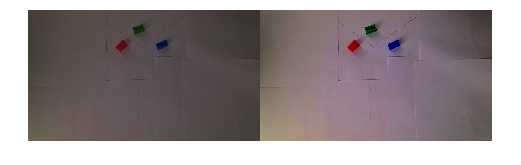

image_rgbadj = imtool(im_rgbadj);

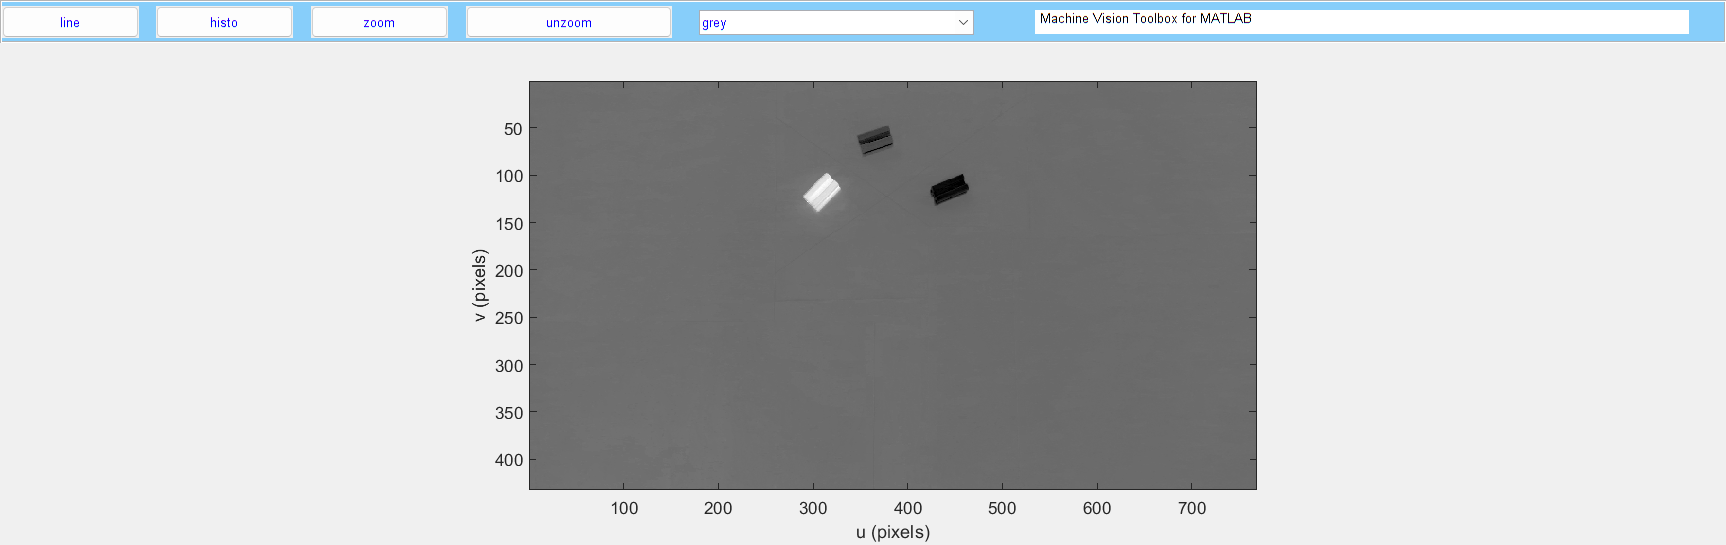

image_rgbadj.Name = "camera image (RGB-adjust)";
close(image_rgbadj) % closes external image window - comment out if you want to keep it open

% Use the adjusted image from now on
im = im_rgbadj;

% Seperate in R/G/B and display
% red
r = R ./(R+G+B); % see help "rdivide, ./"
figure(1); idisp(r,'title',"Grey scale (R)")

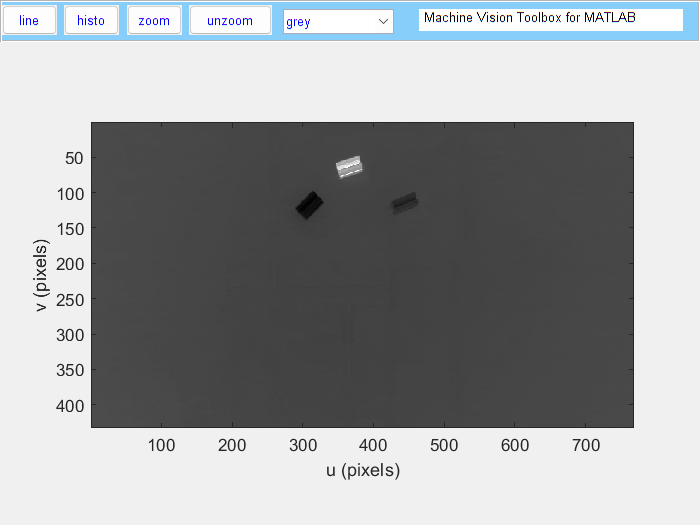

% green
g = G ./(R+G+B);
figure(2); idisp(g,'title',"Grey scale (G)")

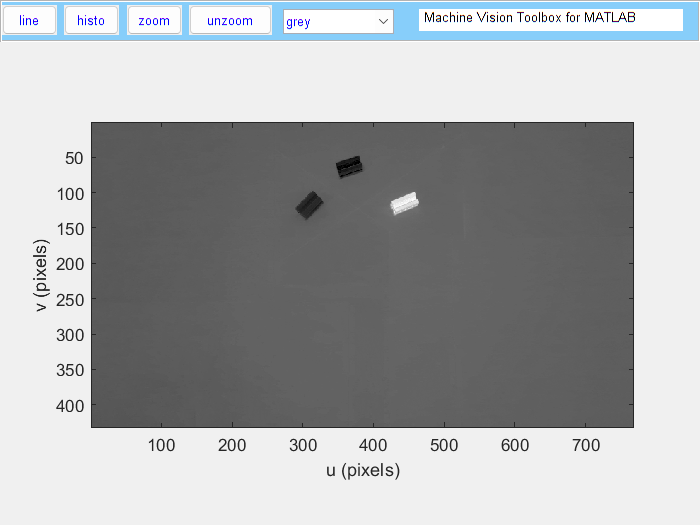

% blue
b = B ./(R+G+B);
figure(3); idisp(b,'title',"Grey scale (B)")

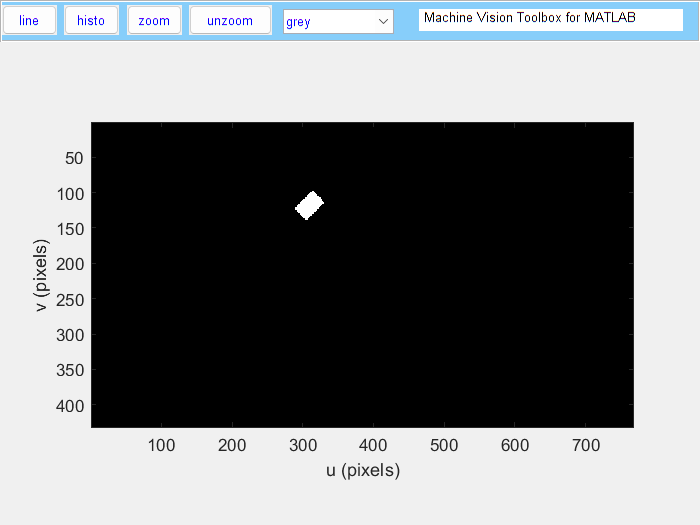


% Define treshhold for the colour and display resulting image
% black is 0, white is 1
% red
r_thresh = r>0.49; % see help "gt, >" 
figure(4); idisp(r_thresh,'title',"Binary scale (R)")

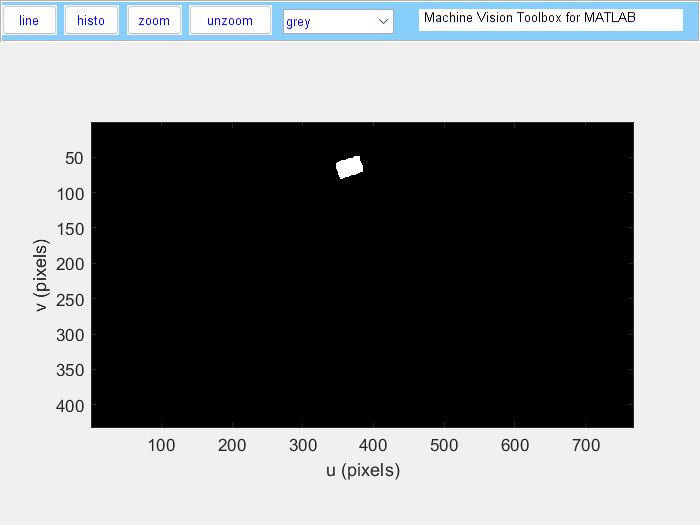

% green
g_thresh = g>0.4;
figure(5); idisp(g_thresh,'title',"Binary scale (G)")

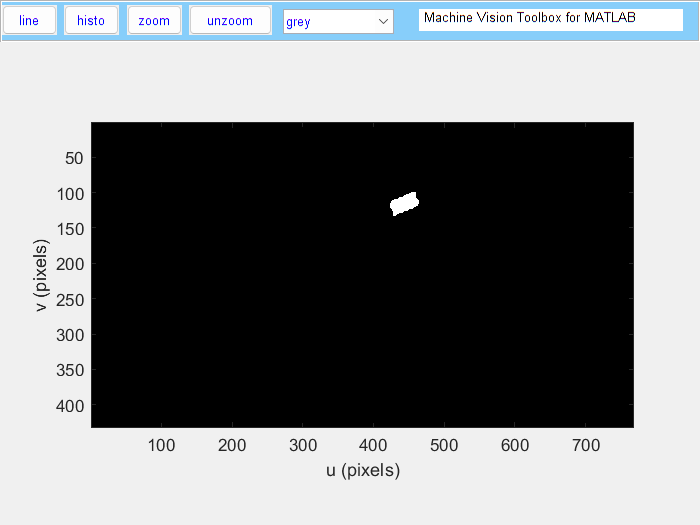

% blue
b_thresh = b>0.4;
figure(6); idisp(b_thresh,'title',"Binary scale (B)")

Generate the center for each object (coloured blocks) and display it.

% display image to mark the detected objects
figure; idisp(im, 'title', 'Gripper poses')

% some common drawing properties
markersize = 15;
linewidth = 1.5;
or_extension = 1.5;

% Red - detect object and draw properties
try
    m_red = iblobs(r_thresh,'area', [500, 50000]);
    m_red.plot_ellipse('edgecolor','k','LineWidth', linewidth);
    m_red.plot('s', 'MarkerSize', markersize, 'MarkerFaceColor','r', 'MarkerEdgeColor','w','LineWidth', linewidth);
    
    % center of first red object
    x_m_red = m_red(1).uc;
    y_m_red = m_red(1).vc;
    m_red_center = [ x_m_red ; y_m_red ];
    
    % drawing orientation
    x_min = x_m_red - cos(m_red(1).theta)*m_red(1).a*or_extension;
    x_max = x_m_red + cos(m_red(1).theta)*m_red(1).a*or_extension;
    y_min = y_m_red - sin(m_red(1).theta)*m_red(1).a*or_extension;
    y_max = y_m_red + sin(m_red(1).theta)*m_red(1).a*or_extension;
    line( [x_min x_max], [y_min y_max], 'Color', 'k', 'LineWidth', linewidth );
    
    disp("Red block found.")
catch ME
    disp("No red block found!")
end

Red block found.



% Green - detect object and draw properties
try
    m_green = iblobs(g_thresh,'area', [500, 50000]);
    m_green.plot_ellipse('edgecolor','k','LineWidth', linewidth);
    m_green.plot('d', 'MarkerSize', markersize, 'MarkerFaceColor','g', 'MarkerEdgeColor','w', 'LineWidth', linewidth);
    
    % center of first green object
    x_m_green = m_green(1).uc;
    y_m_green = m_green(1).vc;
    m_green_center = [ x_m_green ; y_m_green ];
    
    % drawing orientation
    x_min = x_m_green - cos(m_green(1).theta)*m_green(1).a*or_extension;
    x_max = x_m_green + cos(m_green(1).theta)*m_green(1).a*or_extension;
    y_min = y_m_green - sin(m_green(1).theta)*m_green(1).a*or_extension;
    y_max = y_m_green + sin(m_green(1).theta)*m_green(1).a*or_extension;
    line( [x_min x_max], [y_min y_max], 'Color', 'k', 'LineWidth', linewidth );
    
    disp("Green block found.")
catch ME
    disp("No green block found!")
end

Green block found.


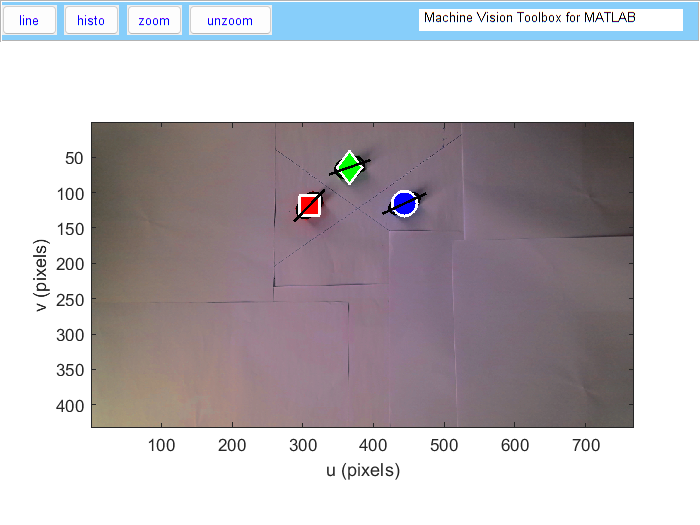

Blue block found.



% Blue - detect object and draw properties
try
    m_blue = iblobs(b_thresh,'area', [500, 50000]);
    m_blue.plot_ellipse('edgecolor','k','LineWidth', linewidth);
    m_blue.plot('o', 'MarkerSize', markersize, 'MarkerFaceColor','b', 'MarkerEdgeColor','w', 'LineWidth', linewidth);
    
    % center of first blue object
    x_m_blue = m_blue(1).uc;
    y_m_blue = m_blue(1).vc;
    m_blue_center = [ x_m_blue ; y_m_blue ];
    
    % drawing orientation
    x_min = x_m_blue - cos(m_blue(1).theta)*m_blue(1).a*or_extension;
    x_max = x_m_blue + cos(m_blue(1).theta)*m_blue(1).a*or_extension;
    y_min = y_m_blue - sin(m_blue(1).theta)*m_blue(1).a*or_extension;
    y_max = y_m_blue + sin(m_blue(1).theta)*m_blue(1).a*or_extension;
    line( [x_min x_max], [y_min y_max], 'Color', 'k', 'LineWidth', linewidth );
    
    disp("Blue block found.")
catch ME
    disp("No blue block found!")
end

## **5. Robot simulation in RoboDK (with Homography)**

Update the RoboDK cell with the calculated position. Therefore you have to do first a 2D to 2D transformation (homography).

if rdk_status == true
    % H_sim: homography matrix for the simulation environment
    % homography with 4 points on a plane
    % image                        simulation_world
    % camara_calibration/Top_L:
        i1 = [ 248 ,  13 ];      w1 = [ -229 , -286 ];
    % camara_calibration/Top_R:
        i2 = [ 505 ,  13 ];      w2 = [   49 , -286 ];
    % camara_calibration/Bot_L:
        i3 = [ 248 , 196 ];      w3 = [ -229 , -483 ];
    % camara_calibration/Bot_R:
        i4 = [ 505 , 196 ];      w4 = [   49 , -483 ];
    % generating the homography matrix
    p1 = [i1(1), i2(1), i3(1), i4(1); i1(2), i2(2), i3(2), i4(2) ];
    p2 = [w1(1), w2(1), w3(1), w4(1); w1(2), w2(2), w3(2), w4(2)];
    % homography matrix in the simulated world
    H_sim = homography(p1, p2);
    
    % H_real: homography matrix for the real world
    % image                        real_world
    % TBD: insert corresponding points %not used
    H_real = homography(p1, p2);  %Currently also Simulation used!
    
    if rdk_real_robot == 1
        H_used = H_real
    else
        H_used = H_sim
    end
    
    % distance above the table to grip the block
    z_grip = 0;
    
    % Red block
    try
        % Calculate center point in world coordinates 
        m_red_center_sim = homtrans(H_used,m_red_center); 
        
        % Transition matrix with translation only
        T_red_1 = [ 1, 0, 0, m_red_center_sim(1);
        	        0, 1, 0, m_red_center_sim(2);
        	        0, 0, 1, z_grip;
        	        0, 0, 0, 1                    ];
        
        % Transition matrix with orientation
        T_red_2 = T_red_1 * rotz(-1 * m_red(1).theta);
        
        % Updating the RDK frame
        Frame = RDK.Item('red_part_calculated_frame');
        Frame.setPose( T_red_2 );
    catch ME
        disp("No red block found!")
    end
    
    % Green block
    try
        % Calculate center point in world coordinates 
        m_green_center_sim = homtrans(H_used,m_green_center); 
        
        % Transition matrix with translation only
        T_green_1 = [ 1, 0, 0, m_green_center_sim(1);
        	          0, 1, 0, m_green_center_sim(2);
        	          0, 0, 1, z_grip;
        	          0, 0, 0, 1                    ];
        
        % Transition matrix with orientation
        T_green_2 = T_green_1 * rotz(-1 * m_green(1).theta);
        
        % Updating the RDK frame
        Frame = RDK.Item('green_part_calculated_frame');
        Frame.setPose( T_green_2 );
    catch ME
        disp("No green block found!")
    end
    
    % Blue block
    try
        % Calculate center point in world coordinates 
        m_blue_center_sim = homtrans(H_used,m_blue_center); 
        
        % Transition matrix with translation only
        T_blue_1 = [ 1, 0, 0, m_blue_center_sim(1);
        	         0, 1, 0, m_blue_center_sim(2);
        	         0, 0, 1, z_grip;
        	         0, 0, 0, 1                    ];
        
        % Transition matrix with orientation
        T_blue_2 = T_blue_1 * rotz(-1 * m_blue(1).theta);
        
        % Updating the RDK frame
        Frame = RDK.Item('blue_part_calculated_frame');
        Frame.setPose( T_blue_2 );
    catch ME
        disp("No blue block found!")
    end

end

The following code performs robot motion in the RoboDK simulation environment.

**NOTE: motions are not optimised and may cause collisions in the real world!**

if rdk_status == true
    % Go to the home position (defined in RoboDK) and open the gripper
    %Go_home()
    %Open_gripper('_')
    RDK_Ur5e_HOME()
    RDK_HandE_DO("activate",["" ""])
    RDK_HandE_DO("open",["" ""])
    
    % Pick the red block
    RDK_Ur5e_MoveL('app_red_calculated_target');
    RDK_Ur5e_MoveL('pick_red_calculated_target');
    RDK_HandE_DO("open_20mm",["pick" "red"])
    RDK_Ur5e_MoveL('app_red_calculated_target');
    
    % Place the red block
    RDK_Ur5e_MoveL('app_place_target');
    RDK_Ur5e_MoveL('place_red_target');
    %Open_gripper('red');
    RDK_HandE_DO("open",["place" "red"])
    RDK_Ur5e_MoveL('app_place_target');
    
    % Pick the green block
    RDK_Ur5e_MoveL('app_green_calculated_target');
    RDK_Ur5e_MoveL('pick_green_calculated_target');
    RDK_HandE_DO("open_20mm",["pick" "green"])
    RDK_Ur5e_MoveL('app_green_calculated_target');
    
    % Place the green block
    RDK_Ur5e_MoveL('app_place_target');
    RDK_Ur5e_MoveL('place_green_target');
    RDK_HandE_DO("open",["place" "green"])
    RDK_Ur5e_MoveL('app_place_target');
    
    % Pick the blue block
    RDK_Ur5e_MoveL('app_blue_calculated_target');
    RDK_Ur5e_MoveL('pick_blue_calculated_target');
    RDK_HandE_DO("open_20mm",["pick" "blue"])
    RDK_Ur5e_MoveL('app_blue_calculated_target');
    
    % Place the blue block
    RDK_Ur5e_MoveL('app_place_target');
    RDK_Ur5e_MoveL('place_blue_target');
    RDK_HandE_DO("open",["place" "blue"])
    RDK_Ur5e_MoveL('app_place_target');
    
    % Go to the home position and open gripper
    %Go_home()
    %Open_gripper('_')
    RDK_Ur5e_HOME()
    RDK_HandE_DO("open",["" ""])
    %
    robot.Disconnect();
end